## Create grid

cla()
ax = gca();

%Create grid
xgrid = 0:1:10;
ygrid = 0:1:10;


a = randi(9)

a = 3

b = randi(9)

b = 5


start_current_position = [a b]

start_current_position =      3     5



xl = arrayfun(@(x)xline(x,'k', "LineWidth",2), xgrid);
yl = arrayfun(@(y)yline(y,'k','LineWidth',2), ygrid);
hold on
ml = arrayfun(@(x)xline(x,'k', "LineWidth",2),xgrid), (rectangle('Position',[a,b,1,1],'FaceColor','g'));

ml =   1×11 ConstantLine array:

    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine    ConstantLine


nl = arrayfun(@(y)yline(y,'k','LineWidth',2),ygrid,'UniformOutput', false), (rectangle('Position',[a,b,1,1],'FaceColor','g'));

nl = 1×11 cell array
    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}    {1×1 ConstantLine}


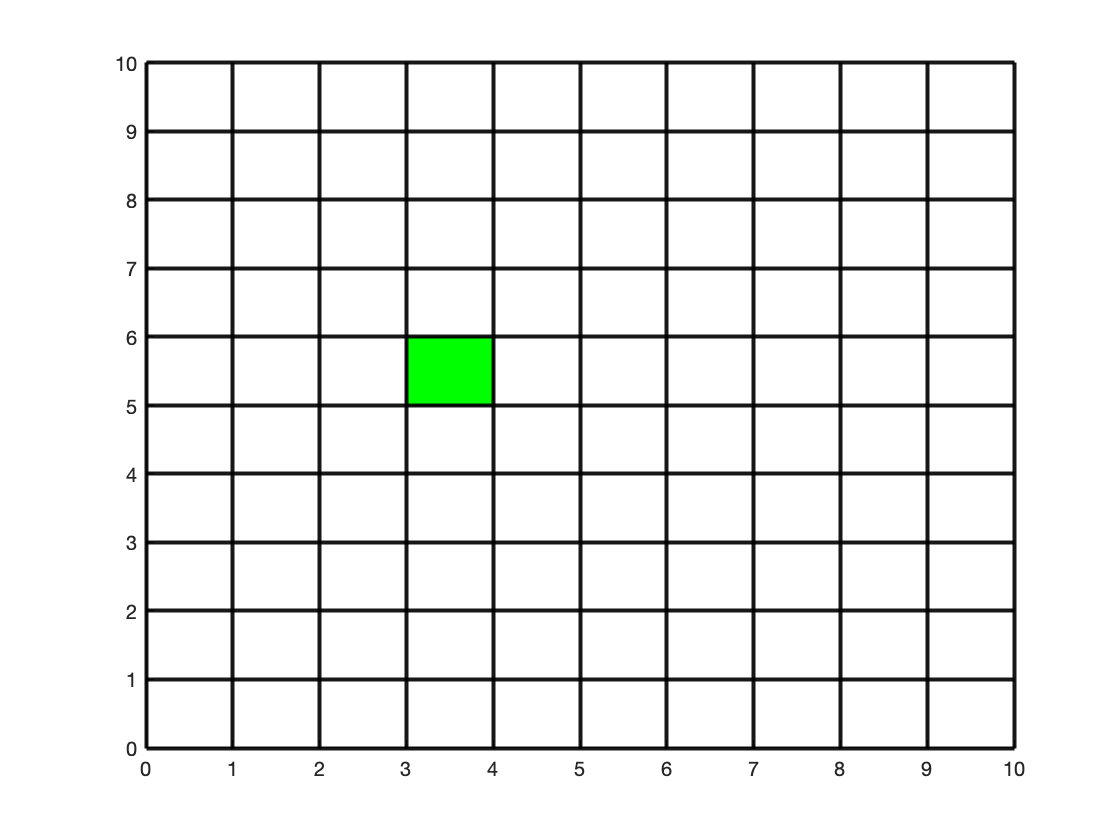

hold on

## Direction types & randomize directions



%Direction types
N = [0,1];
E = [1,0];
S = [0,-1];
W = [-1,0];


% Current_direction = ...if statement numbers correlate to directions
% start position -> if statements -> deciding the directions
% Establishing current direction

if a == 9 && b == 9 
rand_dirc = datasample([1 2 3 4],1,"Weights",[0, 0, 0.50, 0.50])
elseif a == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0.33, 0, 0.33])
elseif b == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0.33, 0.33, 0])
elseif a == 0 && b == 0
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.50, 0.50, 0, 0])
elseif a == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.33, 0, 0.33, 0.33])
elseif b == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0, 0.33, 0.33, 0.33])
elseif a == 9 && b == 0
rand_dirc = datasameple([1 2 3 4],1,"Weights",[0, 0.50, 0.50, 0])
elseif a == 0 && b == 9
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.50, 0, 0, 0.50])
elseif a ~= 9 || a~= 0 && b ~= 9 || b ~= 0 
rand_dirc = datasample([1 2 3 4],1,"Weights",[0.25, 0.25, 0.25, 0.25])
end

rand_dirc = 1


if rand_dirc == 1
new = [a, b+1]
elseif rand_dirc == 2
new = [a+1, b]
elseif rand_dirc == 3
new = [a, b-1]
elseif rand_dirc == 4
new = [a-1, b]
end

new =      3     6


new_scpos = new

new_scpos =      3     6


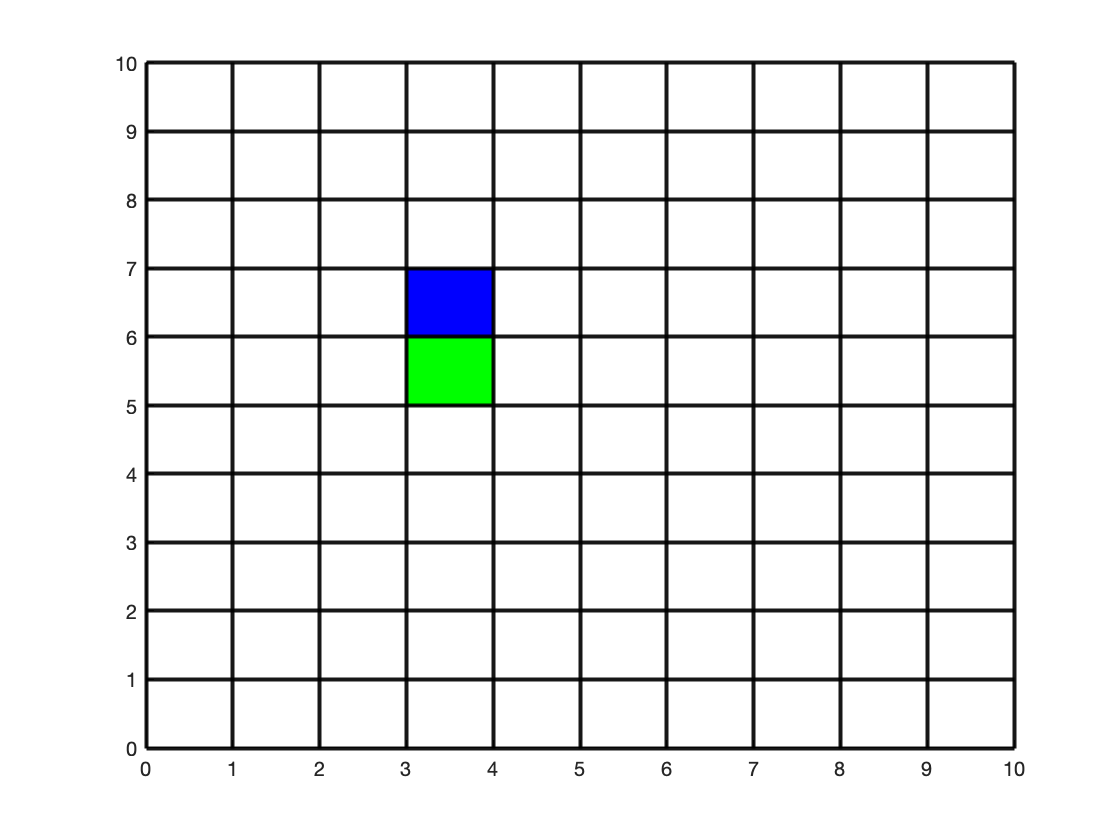


path = rectangle('Position',[new_scpos,1,1], 'FaceColor','b');
hold on

p = new_scpos

p =      3     6


## Create path



%Number of turns
num_turns = 1;
%total path length
path_length = 10;
%The total number of segment lengths
Max_lengths = num_turns+1;
% (randi([0,path_length-Max_lengths],1,Max_lengths-1))
    %Returns size [1xMax_lengths-1] vector of random integers
    %Between 0 and path_length - Max_lengths

%sort the output of the randi array in order from ascending order
    % returns [1xMax_lengths-1] vector of sorted random values in ascending
    % order

%find the diff

% +ones(1,Max_lengths)
c = (diff([0,sort(randi([0,path_length-Max_lengths],1,Max_lengths-1)),path_length-Max_lengths])+ones(1,Max_lengths))

c =      6     4




new_path_dirc = p

new_path_dirc =      3     6


p = new_scpos

p =      3     6


c =      5     4


p =      3     6


new_path_dirc =      3     7


c =      4     4


p =      3     7


new_path_dirc =      3     8


c =      3     4


p =      3     8


new_path_dirc =      3     9


c =      2     4


p =      3     9


new_path_dirc =      3    10


c =      1     4


p =      3    10


new_path_dirc =      3    11


c =      0     4


dirc = 2

new_path_dirc2 =      4    11


p =      4    11


rand_dirc = 2

c =      0     3


p =      4    11


new_path_dirc =      5    11


c =      0     2


p =      5    11


new_path_dirc =      6    11


c =      0     1


p =      6    11


new_path_dirc =      7    11


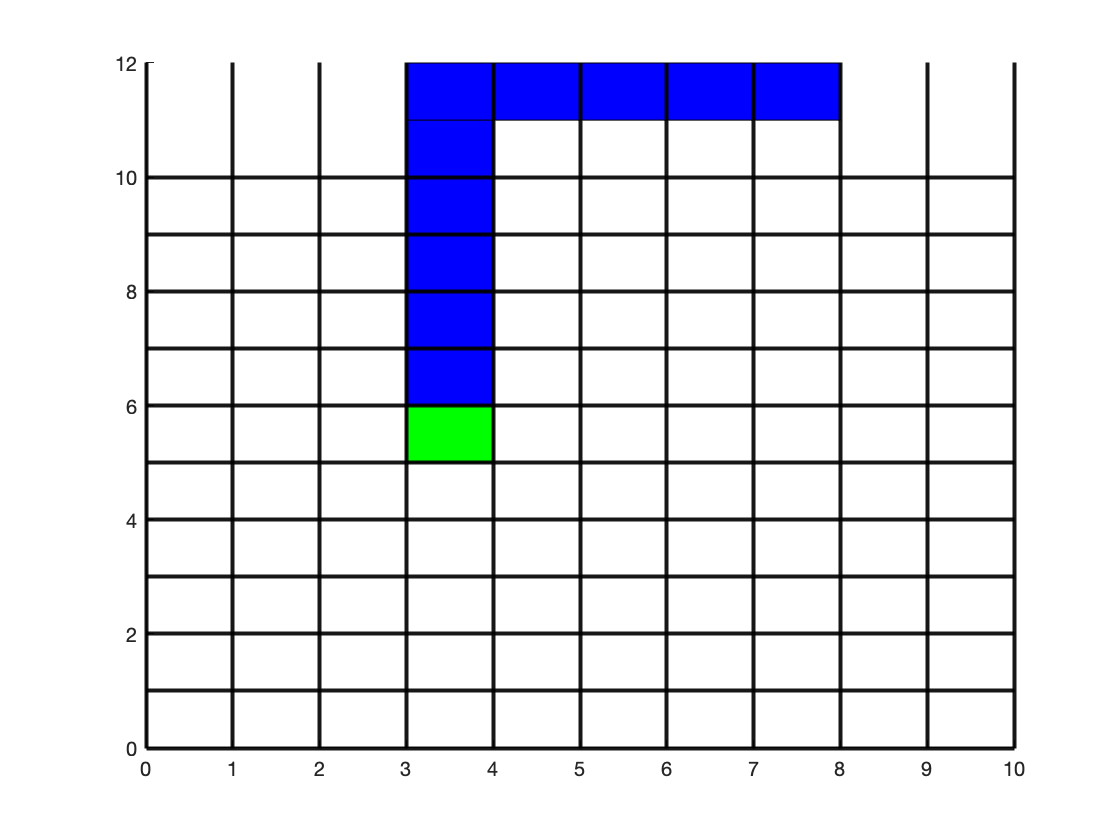

for i = 1:length(c)
for ii = 1:c(i)
if c(i) > 1
c(i) = c(i) - 1 

p = new_path_dirc
% new_path_dirc2 = new_path_dirc
if rand_dirc == 1 
new_path_dirc = [p(1)+0, p(2)+1]
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
end
if rand_dirc == 2
new_path_dirc = [p(1)+1, p(2)+0]
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
end
if rand_dirc == 3
new_path_dirc = [p(1)+0, p(2)-1]
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
end
if rand_dirc == 4
new_path_dirc = [p(1)-1, p(2)+0]
rectangle('Position',[new_path_dirc,1,1], 'FaceColor','b');
end 
end

if c(i) == 1 && i ~= Max_lengths
c(i) = c(i) - 1 
%change direction E W
if rand_dirc == 1 || rand_dirc == 3
dirc = datasample([1 2 3 4],1,"Weights",[0 0.50 0 0.50])
if dirc == 2
new_path_dirc2 = [new_path_dirc(1)+1, new_path_dirc(2)+0]
elseif dirc == 4
new_path_dirc2 = [new_path_dirc(1)-1, new_path_dirc(2)+0]
end
rectangle('Position',[new_path_dirc2,1,1], 'FaceColor','b')
p = new_path_dirc2 
rand_dirc = dirc
new_path_dirc = p;

%change direction N S
elseif rand_dirc == 2 || rand_dirc == 4
dirc = datasample([1 2 3 4],1,"Weights",[0.50 0 0.50 0])
if dirc == 1
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)+1]
elseif dirc == 3
new_path_dirc2 = [new_path_dirc(1)+0, new_path_dirc(2)-1]
end
rectangle('Position',[new_path_dirc2,1,1], 'FaceColor','b')
p = new_path_dirc2
rand_dirc = dirc
new_path_dirc = p;
end
end

% 
% if p(1) <= 0
% dircs = datasample([1 2 3 4],1,"Weights",[0.33 0.33 0.33 0])
% elseif p(1) <= 0 && p(2) <= 0
% dircs = datasample([1 2 3 4],1,"Weights",[0.50 0.50 0 0])
% elseif p(1) <= 0 && p(2) >= 9
% dircs = datasample([1 2 3 4],1,"Weights",[0.50 0 0 0.50])
% elseif p(1) >= 9
% dircs = datasample([1 2 3 4],1,"Weights",[0.33 0 0.33 0.33])
% elseif p(1) >= 9 && p(2) <= 0 
% dircs = datasample([1 2 3 4],1,"Weights",[0 0.50 0.50 0])
% elseif p(1) >= 9 && p(2) >= 9
% dircs = datasample([1 2 3 4],1,"Weights",[0 0 0.50 0.50])
% elseif p(2) >= 9
% dircs = datasample([1 2 3 4],1,"Weights",[0 0.33 0.33 0.33])
% elseif p(2) <= 0
% dircs = datasample([1 2 3 4],1,"Weights",[0.33 0.33 0 0.33])
% end
% 
% 
% if dircs == 1
% new_path_dirc2 = [p(1)+0, p(2)+1]
% elseif dircs == 2
% new_path_dirc2 = [p(1)+1, p(2)+0]
% elseif dircs == 3
% new_path_dirc2 = [p(1)+0, p(2)-1]
% elseif dircs == 4
% new_path_dirc2 = [p(1)-1, p(2)+0]
% rand_dirc = dircs
% dirc = rand_dirc
% p = new_path_dirc2
% new_path_dirc = new_path_dirc2
% end

end
end

## Finish area


% finish_area = rectangle('Position',[0 1 1 1],'FaceColor',[0.5, 0.5, 0.5]);

new_path_dirc2 = new_path_dirc

new_path_dirc2 =      7    11


finish_location =      8    11


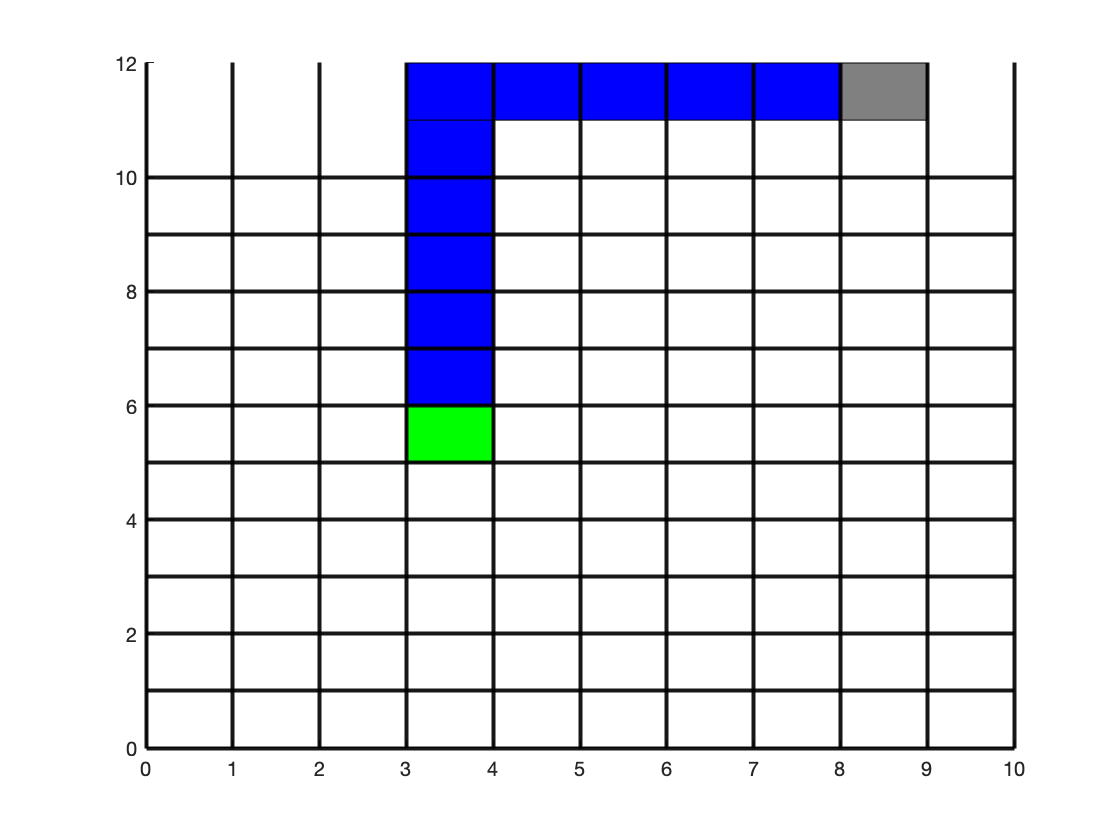

if dirc == 1
finish_location = [new_path_dirc(1)+0, new_path_dirc(2)+1]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end
if dirc == 2
finish_location = [new_path_dirc(1)+1, new_path_dirc(2)+0]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end

if dirc == 3
finish_location = [new_path_dirc(1)+0, new_path_dirc(2)-1]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end
if dirc == 4
finish_location = [new_path_dirc(1)-1, new_path_dirc(2)+0]
rectangle('Position',[finish_location,1,1], 'FaceColor',[0.5 0.5 0.5]);
end   
